# 数理モデル解析特論

## - 数値計算に潜むリスク

- 整数、浮動小数点数

- 数値計算に生じる誤差

- 区間演算

## 数値計算とは？

- ﻿数学の問題を有限桁の浮動小数点数を使って「数値的」に解く。数式処理とは違う

- ﻿数値計算でできること、できないこと

- ﻿数値計算は誤差との戦い

- ﻿整数（integer）と浮動小数点数（binary32/binary64）

## 整数型

MATLABでは、int8、int16、int32、int64という表現方法がある。

a = int32(10); disp(a)

   10


b = int32(2147483647)+int32(1); disp(b)

   2147483647


c = intmax('int32'); disp(c)

   2147483647


﻿int32の最大値が2147483647。﻿実際$\(2^{31}-1=2147483647\)$。﻿これはint32整数が次のようなビットパターンで表現されていることによる。

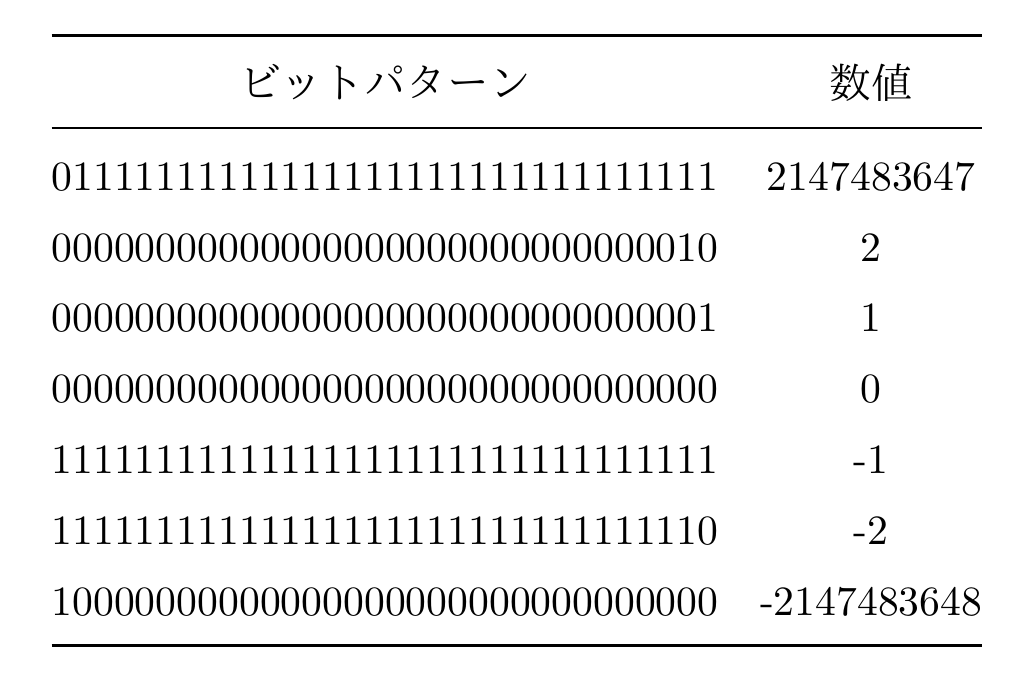 

﻿このような負の数の表現形式を「**2の補数形式**」と呼ぶ。﻿32個の各bitが次のような重みをもっていると考えられる。

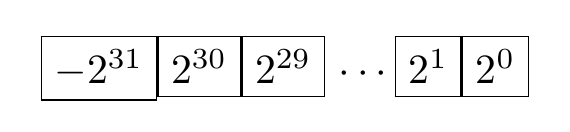

﻿2の補数形式の場合、$\(n\)$ ビットで$\(-2^{n-1}\)〜\(2^{n-1}-1\)$の範囲の数を表現できる。つまり 

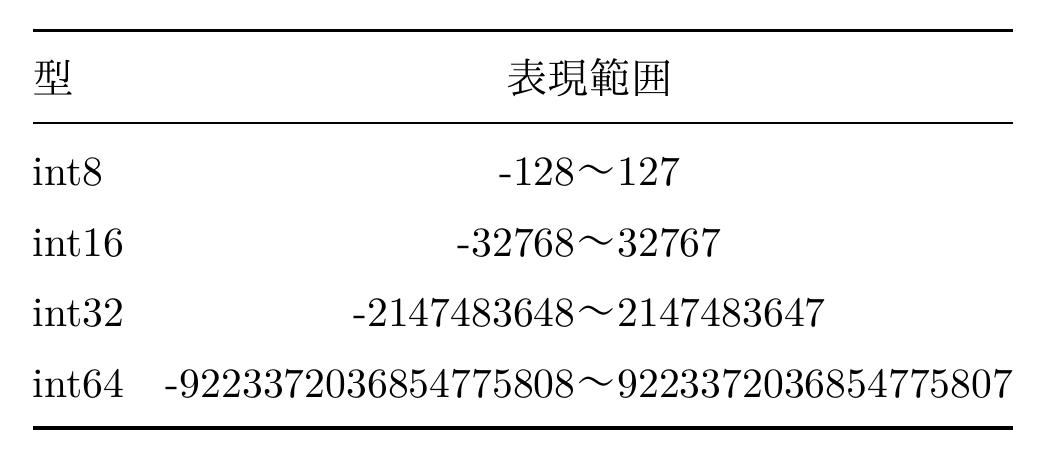

﻿の範囲の整数が表せる。

b = int64(2147483647)+1; disp(b)

   2147483648


b = int64(9223372036854775807)+1; disp(b)

   9223372036854775807


## ﻿浮動小数点数

﻿浮動小数点数は﻿「浮動小数点形式」と呼ばれる形式で表現される数。﻿例えば「$\(1234.5\)$」を「$\(1.2345\times 10^3\)$」のように、小数点の位置を1番左の数値と左から2番目の数値の間に移動（「正規化」と呼ぶ）し、それに指数を掛けた形式で数を表現する。この「$\(1.2345\)$」の部分を「**仮数部**」、「$\(10^3\)$」の部分（厳密には$\(~^3\)$）を「**指数部**」という。

﻿浮動小数点数は仮数部の長さ、指数部の長さ、指数が2・10・16など、多様な規格が考えられる。そこで1985年にWilliam Kahan (University of California at Berkeley) が中心となって「﻿IEEE 754: Standard for Binary Floating-Point Arithmetic」﻿という標準規格が制定された。最近では世に出るハードウェアのほぼ全てがこの規格に従っている。

### ﻿倍精度 (binary64)

﻿倍精度は、符号（$\(\pm\)$）に1ビット。指数部に11ビット。仮数部に52ビットを使う。 全部で64ビット=8バイトである。

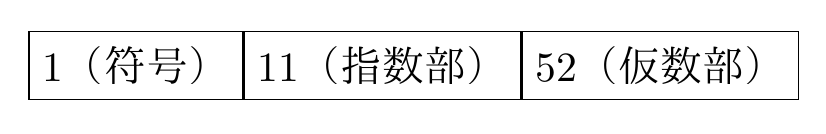

- ﻿符号は、0なら正、1なら負

- ﻿指数部は「$\(\times 2^{\mbox{指数}}\)$」の指数の部分に$\(1023\)$を加えたものが11ビット符号無しの整数の形で格納されている

- ﻿仮数部は、実際の仮数部の先頭の「1」を取り除いた残りが格納されている。仮数部の先頭は必ず1にしてメモリに格納しないことで1ビット分精度を稼いでいる

﻿数値 $\(x\)$ は


$$\[x=\pm\; 1.d_1d_2\cdots d_{52}\times 2^{m}=\pm\left(\frac{1}{2^0}+\frac{d_1}{2^1}+\frac{d_2}{2^2}+\cdots+\frac{d_{52}}{2^{52}}\right)2^{e}_{(10)}\]$$


﻿と書ける（$\(-1022\le e\le 1023\)$、$\(m\)$：$\(e+1023\)$の2進表現）

﻿例えば、5.25は2進数で書くと 


$$\[
101.01_{(2)} = \left(\frac{1}{2^0}+\frac{0}{2^1}+\frac{1}{2^2}+\frac{0}{2^{3}}+\frac{1}{2^4}\right)\times 2^2_{(10)}
\]$$


 であるから、計算機内では

﻿のように格納されている。指数部の「1000000001」は、「2+1023=1025」を2進数にしたもの。﻿これは**正規化数**と呼ばれる数の表現。

x = 5.25;
disp(float2bin(x))

0100000000010101000000000000000000000000000000000000000000000000


disp(float2bin(5.24))

0100000000010100111101011100001010001111010111000010100011110110


binx = float2bin(x);
sign = binx(1); disp(sign)

0


expo  = binx(2:12); disp(expo)

10000000001


frac = binx(13:end); disp(frac)

0101000000000000000000000000000000000000000000000000


﻿符号はsign = 0で正の数、指数部はexp-1023=1025-1023=2、仮数部は

frac=(101000000000000000000000000000000000000000000000000)$\(_2\)$

で2進数表示され、実際の値は1.3125。元の浮動小数点数に戻すと


$$\[(-1)^{\mathrm{sign}}*\mathrm{dfrac}*2^{\mathrm{exp}-1023}=5.25\]$$


で確かに元の数に戻ることがわかる。

dfrac = 1 + sum((frac-'0')./(2.^(1:52))); disp(dfrac)

    1.3125


dexp  = sum((expo-'0').*(2.^(10:-1:0)))-1023;
x = (-1)^(str2double(sign))*dfrac*2^(dexp); disp(x)

    5.2500


﻿次に$\(e\)$の範囲$\(-1022\le e\le 1023\)$に注目する。$\(e+1023\)$が11ビット符号無しの整数なら範囲は$\(0\)$〜$\(2047\)$であるが、$\(e\)$範囲から$\(e+1023=0\)$のときと$\(e+1023=2047\)$のときが使われていない。

これらは**特殊な数を表す**のに使われる。それらは

- ﻿零

- ﻿無限大 (Inf)

- ﻿NaN (Not a Number)

- ﻿非正規化数

﻿と呼ばれる。

## ﻿零

﻿指数部が$\(e+1023=0\)$かつ仮数部が0のとき。


$$\[\pm\; 0.00\cdots 0\times 2^{0}={\pm\left(\frac{0}{2^0}+\frac{0}{2^1}+\frac{0}{2^2}+\cdots+\frac{0}{2^{52}}\right)2^{-1023}}_{(10)}.\]$$


x = 0.0; disp(x), disp(float2bin(x))

     0
0000000000000000000000000000000000000000000000000000000000000000


x = -0.0; disp(x), disp(float2bin(x))

     0
1000000000000000000000000000000000000000000000000000000000000000


## 無限大

﻿$\(e+1023=2047\)$かつ仮数部が0のとき、$\(\pm\infty\)$を表す。


$$\[\pm\; 1.00\cdots 0\times 2^{m}={\pm\left(\frac{1}{2^0}+\frac{0}{2^1}+\frac{0}{2^2}+\cdots+\frac{0}{2^{52}}\right)2^{1024}}_{(10)},\]$$


$\(m\)$: 2047の2進表現. このとき**オーバーフロー**が起こるという。

x = inf; disp(x), disp(float2bin(x))

   Inf
0111111111110000000000000000000000000000000000000000000000000000


disp(-x), disp(float2bin(-x))

  -Inf
1111111111110000000000000000000000000000000000000000000000000000


## NaN﻿ (Not a Number)

﻿$\(e+1023=2047\)$ かつ仮数部が0でないとき。負数の平方根など、不可能な演算の結果を表すのに使われる。

x = inf; disp(float2bin(x))

0111111111110000000000000000000000000000000000000000000000000000


x = nan; disp(x), disp(float2bin(x))

   NaN
1111111111111000000000000000000000000000000000000000000000000000


x = inf-inf; disp(x), disp(float2bin(x))

   NaN
1111111111111000000000000000000000000000000000000000000000000000


x = inf/inf; disp(x), disp(float2bin(x))

   NaN
1111111111111000000000000000000000000000000000000000000000000000


## ﻿正規化数の最大・最小

﻿正の正規化数の最大の数は、$\(e+1023=2046\)$、かつ仮数部のビットが全て1のとき。


$$\[{\left(\frac{{1}}{2^0}+\frac{1}{2^1}+\frac{1}{2^2}+\cdots+\frac{1}{2^{52}}\right)2^{{1023}}}_{(10)}= 2^{1024}-2^{971}\approx10^{308.25}\]$$


であり、これを1ビットでも超えたら無限大になる。これを**オーバーフロー**という。

x = (2^53-1)*2^971; disp(x), disp(float2bin(x))

  1.7977e+308
0111111111101111111111111111111111111111111111111111111111111111


x = (2^53)*2^971; disp(x), disp(float2bin(x))

   Inf
0111111111110000000000000000000000000000000000000000000000000000


﻿正の正規化数の最小の数は、$\(e+1023=1\)$かつ仮数部のビットが全て0のとき。


$$\[{\left(\frac{{1}}{2^0}+\frac{0}{2^1}+\frac{0}{2^2}+\cdots+\frac{0}{2^{52}}\right)2^{-1022}}_{(10)}= 2^{-1022}\approx10^{-307.65}\]$$


であり、これを下回ると**アンダーフロー**というが、IEEE 754では、ここでアンダーフローさせないで「悪あがき」をする。

## ﻿非正規化数

﻿指数部が$\(e+1023=0\)$かつ仮数部が0でないとき、仮数部の最初の桁を$\(0\)$にして


$$\[\pm\; 0.d_1d_2\cdots d_{52}\times 2^{0}={\pm\left(\frac{{0}}{2^0}+\frac{d_1}{2^1}+\frac{d_2}{2^2}+\cdots+\frac{d_{52}}{2^{52}}\right)2^{{{-1022}}}}_{(10)}.\]$$


%

という数の表現をする。 非正規化数は文字通り「正規化していない」数。

x = 2^(-1022); disp(x), disp(float2bin(x))

  2.2251e-308
0000000000010000000000000000000000000000000000000000000000000000


disp(float2bin(x-2^(-1074)))

0000000000001111111111111111111111111111111111111111111111111111


### 漸近アンダーフロー

﻿正規化数の最小数の最終bitを1だけ減らすと


$$\[{\left(\frac{{0}}{2^0}+\frac{1}{2^1}+\frac{1}{2^2}+\cdots+\frac{1}{2^{52}}\right)2^{-1022}}_{(10)}\]$$


となり、これを正規化すると


$$\[{\left(\frac{{1}}{2^0}+\frac{1}{2^1}+\frac{1}{2^2}+\cdots+\frac{0}{2^{52}}\right)2^{-1023}}_{(10)}\]$$


となって、指数部の下限$\(-1022\le e\)$を超えてしまう。そこで、「$\(2^{-1022}\)$**を下回ったら正規化をやめて指数部を**$\(2^{-1022}\)$**に固定して仮数部の最初の桁を**$$0$$**としてみて格納する**」とする。これが非正規化数であり、


$$\[{\left(\frac{{0}}{2^0}+\frac{1}{2^1}+\frac{1}{2^2}+\cdots+\frac{1}{2^{52}}\right)2^{-1022}}_{(10)}\]$$



$$\[{\left(\frac{{0}}{2^0}+\frac{1}{2^1}+\frac{1}{2^2}+\cdots+\frac{0}{2^{52}}\right)2^{-1022}}_{(10)}\]$$



$$\[\vdots\]$$



$$\[\left(\frac{{0}}{2^0}+\frac{1}{2^1}+\frac{0}{2^2}+\cdots+\frac{0}{2^{52}}\right)2^{-1022}\]$$



$$\[{\left(\frac{{0}}{2^0}+\frac{0}{2^1}+\frac{1}{2^2}+\cdots+\frac{1}{2^{52}}\right)2^{-1022}}_{(10)}\]$$



$$\[\vdots\]$$



$$\[{\left(\frac{{0}}{2^0}+\frac{0}{2^1}+\frac{0}{2^2}+\cdots+\frac{1}{2^{52}}\right)2^{-1022}}_{(10)}=2^{-1074}\approx10^{-323.31}\]$$


のような数が表現できる。ただし、$\(2^{-1022}\)$と$\(2^{-1074}\)$の間の数は、本来53ビットあるべき仮数部の長さが52ビット〜1ビットまで減ってしまっており、精度が低下していることに注意。

x = 2^(-1074); disp(x), disp(float2bin(x))

  4.9407e-324
0000000000000000000000000000000000000000000000000000000000000001


disp(x/2), disp(float2bin(x/2))

     0
0000000000000000000000000000000000000000000000000000000000000000


## 浮動小数点数まとめ

﻿倍精度　(binary64) は

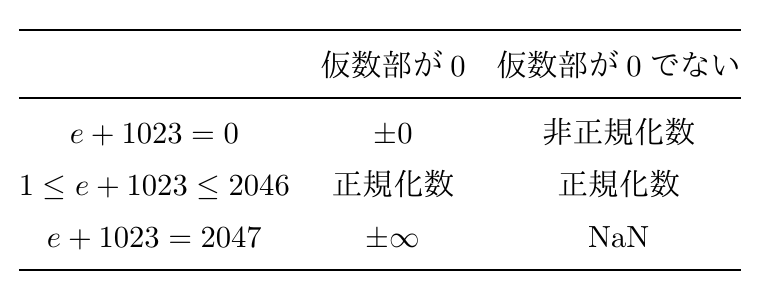

﻿単精度 (binary32) は

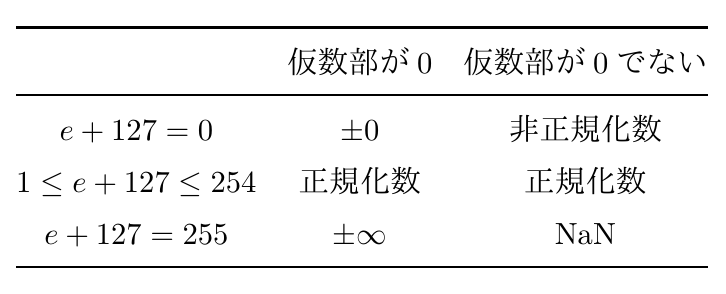

﻿今後、浮動小数点数全体の集合を$\(\mathbb{F}\)$と表すことにする。特に断りがなければ、浮動小数点数は倍精度浮動小数点数（64bit）とする。IEEE754では**binary64**と呼ばれている。

## 丸め誤差

﻿浮動小数点数を使用した演算に混入する誤差について述べる。浮動小数点数同士の演算（加減乗除など）の結果は、浮動小数点数で表せるとは限らない。例えば、10進数で仮数部3桁の浮動小数点演算を考え、2/3を計算すると、


$$\[2.00\times 10^0/3.00\times 10^0=0.66666666...\times 10^0\]$$


となり、仮数部3桁に収まらない。仮数部の4桁目で四捨五入を行うと


$$\[6.67\times10^{-1}\]
$$


となる。このときの計算値と真値との差


$$\[6.67\times10^{-1}-6.6666666...\times10^{-1}=3.3333333\times10^{-4}\]$$


が丸め誤差である。

IEEE 754は2進数浮動小数点数なので、基本的には0捨1入で丸められる。例えば、10進数の「0.1」をIEEE 754のdoubleに変換してみると


$$\[
0.1_{(10)} = 0.000110011001100110011..._{(2)}
 = 1.10011001100110011...\times 2^{m},
\]$$


$\(m\)$は$\(-4+1023=1019\)$の2進表現、つまり$\(m=01111111011\)$.仮数部は無限小数になっているのでそのまま格納出来ない。 小数点以下を52bit以内とそれ以降で区切って表示すると

となり、はみ出た部分の先頭が「1」なので、0捨1入で繰り上げる。最終的には、 10進数の「0.1」は

のように格納されている。

x = 0.1; disp(float2bin(x))

0011111110111001100110011001100110011001100110011001100110011010


﻿10進数の0.1は計算機には正確に格納できず、少しだけ0.1より大きい値で格納されており、**丸め誤差**が含まれている

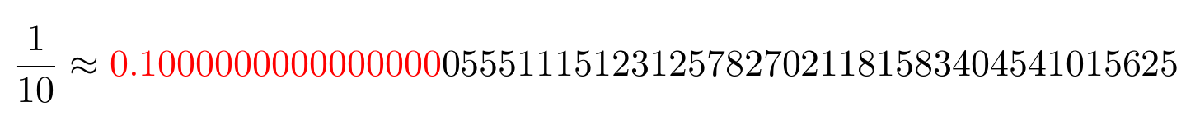

x = 0.1;
fprintf('%.55f\n',x)

0.1000000000000000055511151231257827021181583404541015625


for i=2:100
  x = x+0.1;
end
fprintf('%.55f\n',x)

9.9999999999999804600747665972448885440826416015625000000


## 丸めの制御 -direct rounding-

﻿IEEE754では、4つの丸めモードを用意している。$\(\tilde x\)$ を実数（$\(\tilde x\in\mathbb{R}\)$）とする。いま実数 $\(\tilde x\)$ が


$$\[\tilde x=\pm\left(\frac{1}{2^0}+\frac{d_1}{2^1}+\frac{d_2}{2^2}+\dots\right)2^{e}_{(10)}\]$$


であるときに、その近似


$$\[x=\pm\left(\frac{1}{2^0}+\frac{d_1}{2^1}+\frac{d_2}{2^2}+\cdots+\frac{d_{52}}{2^{52}}\right)2^{e}_{(10)}\in\mathbb{F}\]$$


を採用する丸めは**原点方向への丸め**（切り捨て）と呼ばれている。

また $\(\tilde x\)$の近似として誤差$\(|x-\tilde{x}|\)$の値が最小になる$\(x\in\mathbb{F}\)$、すなわち


$$\[|x-\tilde{x}|=\min_{y\in\mathbb{F}}|y-\tilde{x}|\]$$


をみたす$\(x\in\mathbb{F}\)$ を採用する方法を**最近点への丸め**という。しかし$\(\tilde x\)$ が2つの浮動小数点数


$$\[x_1=\left(\frac{1}{2^0}+\frac{d_1}{2^1}+\frac{d_2}{2^2}+\cdots+\frac{d_{52}}{2^{52}}\right)2^{e}_{(10)},~~~x_2=\left(\frac{1}{2^0}+\frac{d_1}{2^1}+\frac{d_2}{2^2}+\cdots+\frac{d_{52}+1}{2^{52}}\right)2^{e}_{(10)}\]$$


の中点となると$\(|x_1-\tilde{x}|=|x_2-\tilde{x}|\)$が成り立ち、$\(x\)$ は一つに決まらない。このときは**仮数部の最後のビットが0**になる方に丸めが実行される。これを**最近偶数への丸め**という。

eps = 2^(-52);
x = 1 + eps/4;   fprintf('%.50f\n',x), disp(float2bin(x))

1.00000000000000000000000000000000000000000000000000
0011111111110000000000000000000000000000000000000000000000000000


y = 1 + 3*eps/4; fprintf('%.50f\n',y), disp(float2bin(y))

1.00000000000000022204460492503130808472633361816406
0011111111110000000000000000000000000000000000000000000000000001


z = 1 + eps/2;   fprintf('%.50f\n',z), disp(float2bin(z))

1.00000000000000000000000000000000000000000000000000
0011111111110000000000000000000000000000000000000000000000000000


x = 2;         fprintf('%.50f\n',x), disp(float2bin(x))

2.00000000000000000000000000000000000000000000000000
0100000000000000000000000000000000000000000000000000000000000000


y = 2 - eps;   fprintf('%.50f\n',y), disp(float2bin(y))

1.99999999999999977795539507496869191527366638183594
0011111111111111111111111111111111111111111111111111111111111111


z = 2 - eps/2; fprintf('%.50f\n',z), disp(float2bin(z))

2.00000000000000000000000000000000000000000000000000
0100000000000000000000000000000000000000000000000000000000000000


﻿次は$\(\tilde{x}\)$よりも必ず大きな $\(a\in\mathbb{F}\)$、すなわち


$$\[a=\min\left\{x\in\mathbb{F}:x\ge\tilde{x}\right\}\]$$


をみたす $\(a\in\mathbb{F}\$ を採用する方法を$\(+\infty\)$**方向への丸め**（上向き丸め）という。逆に $\(\tilde{x}\)$ よりも必ず小さな$\(b\in\mathbb{F}\)$、すなわち


$$\[b=\max\left\{x\in\mathbb{F}:x\le\tilde{x}\right\}\]$$


をみたす $\(b\in\mathbb{F}\)$ を採用する方法を$\(-\infty\)$**方向への丸め**（下向き丸め）という。これらより


$$\[ b\le\tilde{x}\le a \]$$


が常に成立する。特に精度保証付き数値計算ではこの2つの丸めモードを利用することで、厳密な包含を得ることができるようになる。まとめると

- ﻿最近点への丸め（デフォルト）：$\(\tilde{x}\)$ に最も近い浮動小数点数に丸める。もし2点あるならば仮数部の最後のビットが0である浮動小数点数に丸める

- ﻿$\(+\infty\)$方向への丸め：$\(\tilde{x}\)$ 以上の浮動小数点数の中で最も小さい浮動小数点数に丸める

- ﻿$\(-\infty\)$方向への丸め：$\(\tilde{x}\)$ 以下の浮動小数点数の中で最も大きい浮動小数点数に丸める

- ﻿原点方向への丸め：絶対値が $\(\tilde{x}\)$ 以下の浮動小数点数の中で、$\(\tilde{x}\) $に最も近いものに丸める

## その他の誤差いろいろ

﻿丸め誤差は実数を浮動小数点数で近似する際の不正確さであった。ここでは浮動小数点数を用いた演算の問題点を紹介する。

### 桁落ち (cancelation)

﻿極めて近い数どうしの減算によって、誤差が著しく大きくなってしまう現象。2つの浮動小数点数


$$\[x=\left(\frac{1}{2^0}+\frac{d_1}{2^1}+\dots+\frac{d_p}{2^p}+\frac{1}{2^{p+1}}+\cdots+\frac{b_{p+2}}{2^{p+2}}+\dots+\frac{b_{52}}{2^{52}}\right)2^{e}_{(10)},\]$$



$$ \[y=\left(\frac{1}{2^0}+\frac{d_1}{2^1}+\dots+\frac{d_p}{2^p}+\frac{0}{2^{p+1}}+\cdots+\frac{c_{p+2}}{2^{p+2}}+\dots+\frac{c_{52}}{2^{52}}\right)2^{e}_{(10)}\]$$


が $\(x>y\)$ とし、仮数部の最初から $ \(p\)$ ビットが等しいとする。このとき


$$\[x-y=\left(\frac{1}{2^0}+\frac{b_{p+2}-c_{p+2}}{2^1}+\dots+\frac{b_{52}-c_{52}}{2^{52-p-1}}\right)2^{e-p-1}_{(10)}\]$$


これよりもともと $\(52\)$ 個あった仮数部の情報が、$\(52-p\)$ 個に減っている。例を挙げよう。$\(b>0\)$ とし、2次方程式 $\(x^2+bx+c=0\)$ の解の公式


$$\[x_1=\frac{-b+\sqrt{b^2-4c}}{2},~x_2=\frac{-b-\sqrt{b^2-4c}}{2}\]$$


を考える。いまもしも $\(b^2\gg c\)$ となるならば、$\(b\)$ と $\(\sqrt{b^2-4c}\)$ が近い数になるので、$\(x_1\)$ の分子の計算で、桁落ちが起こる。

b = 1e15; c = 1e14;
x1 = (-b+sqrt(b^2-4*c))/2; disp(x1), disp(x1^2+b*x1+c)

   -0.1250
  -2.5000e+13


x2 = 2*c/(-b-sqrt(b^2-4*c)); disp(x2), disp(x2^2+b*x2+c)

   -0.1000
     0


### ﻿情報落ち (lost of information)

﻿絶対値の大きさが極端に違う2数の加減算を行った時、小さいほうの数値の下位の桁が失われてしまう現象。

format long
disp((3.14159265358979+1e10)-1e10)

   3.141592025756836


disp(3.14159265358979 + (1e10-1e10)),format short

   3.141592653589790


disp(1e48+543.2-1e48-1e36+123.4+1e36)

     0


disp(1e48-1e48-1e36+1e36+543.2+123.4)

  666.6000


disp(1e48-1e36-1e48+1e36+543.2+123.4)

  -3.9231e+30


### 打ち切り誤差 (truncation error)

﻿無限回行うべき計算を有限回の計算で置き換えることにより生じる誤差。計算機は有限回の四則演算しかできない。そのため、無限級数や収束列のような値を求めるためには、有限項で打ち切った近似値を用いる。その際に誤差が生じる。（例）Taylor展開の打ち切り誤差、Newton法の打ち切り誤差、数値積分の打ち切り誤差

disp(exp_taylor(20))

   4.8517e+08


disp(exp(20))

   4.8517e+08


disp(exp_taylor(-20))

   6.1476e-09


disp(exp(-20))

   2.0612e-09


## 区間演算 (require INTLAB)

﻿区間の表現、区間演算について述べる。精度保証付き数値計算の基本的な原理は、実数値で与えられる真の値の上限と下限を浮動小数点数により浮動小数点演算を用いて包み込むことである。

$\(\mathbb{R}\)$ 上の区間を


$$\[{\bf a}:=\{x\in\mathbb{R}:\underline{a}\le x\le\overline{a},~\underline{a}, \overline{a}\in\mathbb{R}\}=[\underline{a}, \overline{a}]\]$$


と表し、区間の全体を $\(\mathbb{IR}\)$ とする。 この時 $ \(\underline{a}\)$ を区間の下端、$\(\overline{a}\)$ を区間の上端という。 さらに区間の


$$\[
\begin{array}{ll}
\mbox{直径（diameter）:}&\mathrm{d}({\bf a})=\overline{a}-\underline{a}\in\mathbb{R}\\
\mbox{半径（radious）:}&\mathrm{rad}({\bf a})=\frac{\overline{a}-\underline{a}}{2}\in\mathbb{R}\\
\mbox{中点（center）:}&\mathrm{mid}({\bf a})=\frac{\overline{a}+\underline{a}}{2}\in\mathbb{R}\\
\mbox{最小絶対値:}&\mathrm{mig}({\bf a})=\min\{|a|:a\in{\bf a}\}\in\mathbb{R}\\
\mbox{最大絶対値:}&\mathrm{mag}({\bf a})=\max\{|a|:a\in{\bf a}\}\in\mathbb{R}\\
\end{array}
\]$$


をそれぞれ表すとする。

a = infsup(-1,2); disp(a)

[   -1.0000,    2.0000] 


disp(['d(a) = ', num2str(diam(a))])

d(a) = 3


disp(['rad(a) = ', num2str(rad(a))])

rad(a) = 1.5


disp(['mid(a) = ', num2str(mid(a))])

mid(a) = 0.5


disp(['mig(a) = ', num2str(mig(a))])

mig(a) = 0


disp(['mag(a) = ', num2str(mag(a))])

mag(a) = 2


### ﻿区間演算（上端下端型）

﻿区間 $\({\bf X}=[a,b]\)$, $\({\bf Y}=[c,d]\)$ に対して、四則演算を定義する：


$$\[
\begin{array}{l}
{\bf X}+{\bf Y}=[a+c,b+d]\\
{\bf X}-{\bf Y}=[a-d,b-c]\\
{\bf X}\times{\bf Y}=[\min\{ac,ad,bc,bd\},\max\{ac,ad,bc,bd\}]\\
{\bf X}\div{\bf Y}=[\min\{a/c,a/d,b/c,b/d\},\max\{a/c,a/d,b/c,b/d\}]
\end{array}
\]$$


$\(\times,~\div\)$ は場合分けをする。

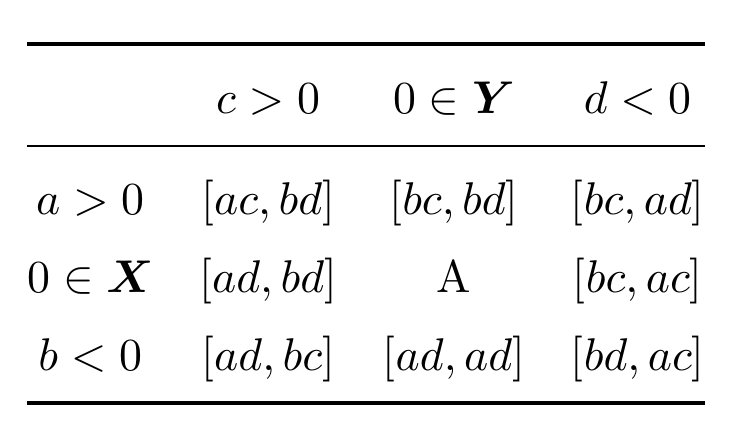

﻿ただし A $\(=[\min\{ad,bc\},\max\{ad,bc\}].\)$

**注意：**﻿区間内全ての要素について演算を行うため無限回の計算が必要のように思えるが、これをまとめて実現するのが区間演算。さらに除算で割る区間 $\({\bf Y}\)$ に0が含まれる（$\(0\in{\bf Y}\)$）と演算結果は無限大を含むことになる。

X = infsup(-2,1);
Y = infsup(1,3);
disp(X+Y)

[   -1.0000,    4.0000] 


disp(X-Y)

[   -5.0000,    0.0000] 


disp(X*Y)

[   -6.0000,    3.0000] 


disp(X/Y)

[   -2.0000,    1.0000] 


Z = Y/X; disp(Z)

[     - Inf,       Inf] 


﻿最後の+/-Infは区間 $$[-\infty,\infty]$$ を表している。

包含関係の単調性が成立する。すなわち $\({\bf X}_1\subseteq {\bf X}_2\)$ かつ $\({\bf Y}_1\subseteq {\bf Y}_2\)$ ならば $\({\bf X}_1\circ{\bf Y}_1\subseteq {\bf X}_2\circ{\bf Y}_2\)$ が成立する。ここで、$\(\circ\in\{+,-,\times,\div\}\)$とする。さらに $\(+\), \(\times\)$ に関しては、交換則と結合則が成立する.


$$\[{\bf X} \circ {\bf Y}={\bf Y}\circ {\bf X},~{\bf X}\circ({\bf Y}\circ{\bf Z})=({\bf X}\circ{\bf Y})\circ{\bf Z},~\circ\in\{+,\times\}.\]$$


しかし、加法と乗法の逆元は存在しない。すなわち分配則が成立しない。劣分配則のみ成立する。


$$\[{\bf X}({\bf Y}+{\bf Z})\subseteq{\bf X}{\bf Y}+{\bf X}{\bf Z}.\]$$


X = infsup(-1,1);
Y = infsup(1,2);
Z = infsup(-2,1);
disp(X*(Y+Z))

[   -3.0000,    3.0000] 


disp(X*Y+X*Z)

[   -4.0000,    4.0000] 


disp(in(X*(Y+Z),X*Y+X*Z))

   1


### 区間演算（中心半径型）

﻿上端下端型区間の他に区間を中心と半径で表す型もある。それを**中心半径型区間**という。中心半径型（mid-rad 型）区間は実数 $\(x\in\mathbb{R}\)$ に対して、区間の中心を $\(x_c\)$、半径を $\(x_r\)$ としたとき


$$\[{\bf x}=\langle x_c,x_r\rangle=\left\{x:x_c-x_r\le x\le x_c+x_r\right\}\]$$


と表される。中心半径型区間と上端下端型区間の間には次のような関係が成り立つ：


$$\[{\bf x}=[\underline{x},\overline{x}]=[x_c-x_r,x_c+x_r]=\left\langle\frac{\underline{x}+\overline{x}}{2},\frac{\underline{x}-\overline{x}}{2}\right\rangle=\langle x_c,x_r\rangle={\bf x}\]$$


中心半径型区間 $\({\bf x}=\langle x_c,x_r\rangle\)$, $\({\bf y}=\langle y_c,y_r\rangle\)$ に対して、四則演算を定義する。


$$\[
\begin{array}{l}
{\bf x}+{\bf y}&=\langle x_c+y_c,x_r+y_r\rangle\\
{\bf x}-{\bf y}&=\langle x_c-y_c,x_r+y_r\rangle\\
{\bf x}\times{\bf y}&\subseteq\langle x_cy_c,|x_c|y_r+|y_c|x_r+x_ry_r\rangle\\
{\bf x}\div{\bf y}&=\frac{{\bf x}\times{\bf y}}{\underline{y}\overline{y}}=\frac{{\bf x}\times{\bf y}}{y_c^2-y_r^2}
\end{array}
\]$$


ちなみに乗算は$\(\mathop{\mathrm{sgn}}(\dot)\)$を括弧内の符号を返す関数とすると


$$\[{\bf x}\times{\bf y}=\langle x_cy_c+\delta_1,\delta_2\rangle\]$$


と書ける。ここで


$$\[
\begin{array}{l}
\delta_1=\mathop{\mathrm{sgn}}(x_cy_c)\min\left\{x_r|y_c|,|x_c|y_r,x_ry_r\right\},\\
\delta_2=\max\left\{x_r(|y_c|+y_r),(|x_c|+x_r)y_r,x_r|y_c|+|x_c|y_r\right\}
\end{array}
\]$$


である。

X = midrad(0,1);
Y = midrad(1.5,0.5);
Z = midrad(-0.5,1.5);
format midrad
disp(X+Y)

<    1.5000,   1.5000> 


disp(X-Y)

<   -1.5000,   1.5000> 


disp(X*Y)

<    0.0000,   2.0000> 


disp(X/Y)

<    0.0000,   1.0000> 


### 関数の値域評価

﻿$\({\bf I}\in\mathbb{IR}\)$ をある区間とし、$\(f:D\subset\mathbb{R}\to\mathbb{R}\)$ を領域 $\(D\)$ で連続な関数とする。 このとき関数 $\(f\)$ は $\(\mathbb{IR}\)$ 上の関数として拡張できる。


$$\[f({\bf I})=\{f(x):x\in{\bf I}\}\]$$


この $\(f({\bf I})\)$ は関数の値域で、これを厳密に計算することは非線形関数の場合不可能である。よって


$$\[f({\bf I})\subseteq [a,b]\]$$


となる区間 $\([a,b]\)$ で関数の値域を包含する。これを $\(f\)$ の区間 $\({\bf I}\)$ における**区間拡張**（区間拡張は一意的でないことに注意！）といい、$\(f_{[\,]}({\bf I})=[a,b]\)$ と表す。

**注意：**﻿IEEE 754標準規格に準拠していても、丸め制御が正しく動いている演算は「**四則演算**・**平方根**」だけ。それ以外の関数（例えば、$\(\sin\)$、$\(\exp\)$ などは）丸めの向きの変更だけでは正しい計算が不可能（**自作するか、丸めに対応し作成されたものを使う**こと）。ただし、デフォルトの関数も精度が十分に高く作られているため、精度保証などを考えない場合はそれで十分。

#### 例

﻿例えば、関数 $\(f(x)=x^2+2x\)$ を考える。関数に区間を単純に代入すると


$$\[
\begin{array}{rl}
x&\in[0.9,1.1]\\
x^2&\in[0.81,1.21]\\
2x&\in[1.8,2.2]\\
x^2+2x&\in[2.61,3.41]\\
\end{array}
\]$$


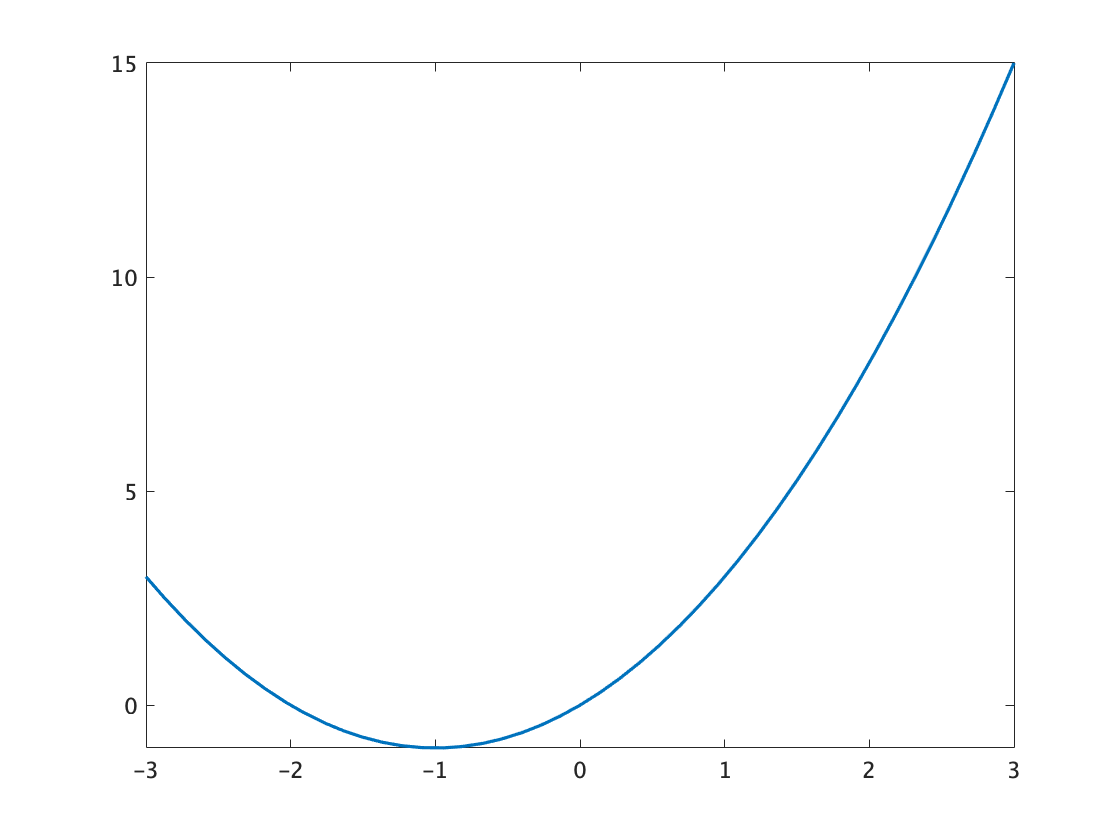

format infsup
f = @(x) x.^2+2*x;
LW = 'linewidth'; lw = 1.6;
fplot(f,[-3,3],LW,lw)

f(infsup(0.9,1.1))

intval ans = 
[    2.6099,    3.4101] 


disp(f(0.9))

    2.6100


disp(f(1.1))

    3.4100


﻿$\(f(x)=x^2+2x\)$ のときは値域評価が区間拡張を利用しても精度が良い。一方で $\(f(x)=x^2-2x\)$ のときは


$$\[
\begin{array}{rl}
x&\in[0.9,1.1]\\
x^2&\in[0.81,1.21]\\
2x&\in[1.8,2.2]\\
x^2-2x&\in[-1.39,-0.59]\mbox{（幅0.8!）}\\
\end{array}
\]$$


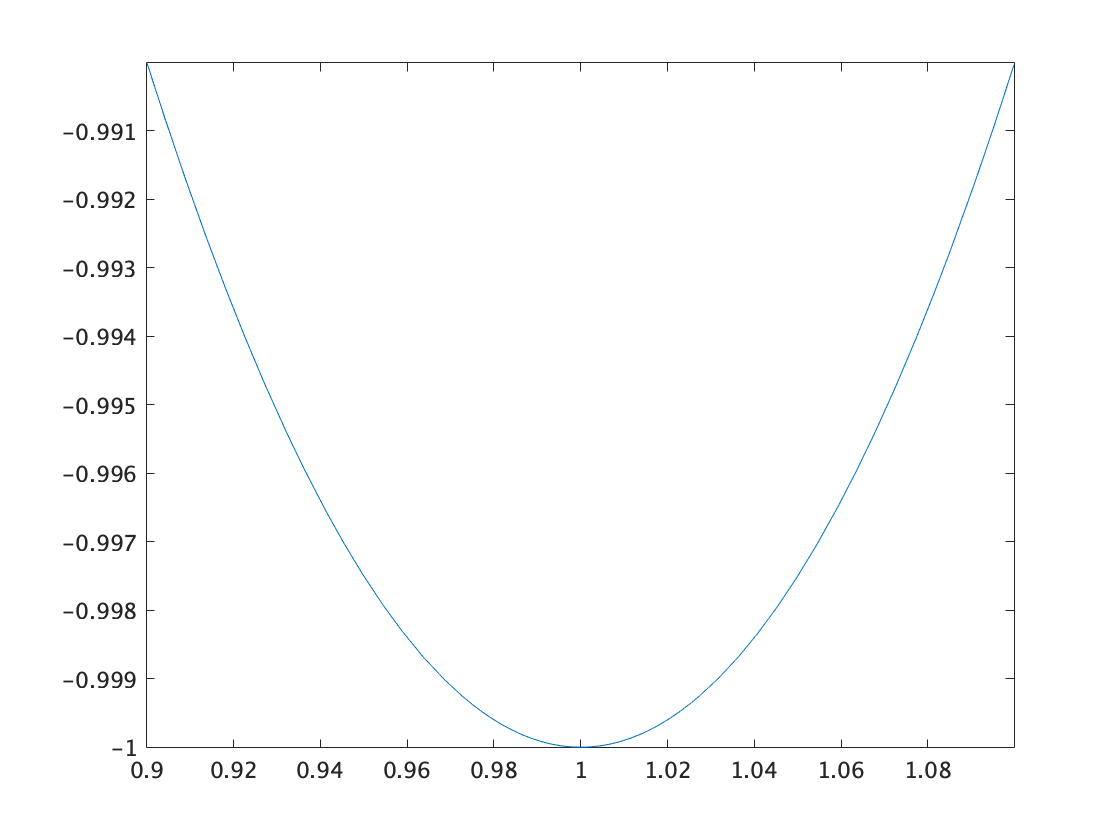

f = @(x) x.^2-2*x;
fplot(f,[0.9,1.1])

disp(f(0.9))

   -0.9900


disp(f(1))

    -1


disp(f(1.1))

   -0.9900


﻿これから値域は $\([-1,-0.99]\)$、一方で区間演算による区間拡張は $\([-1.39,-0.59]\)$。だいぶ過大評価になってしまう。そこで区間幅を改良したい。

#### アイディア1：$\(f(x)=x(x-2)\)$


$$\[
﻿\begin{array}{l}
&x\in[0.9,1.1]\\
&x(x-2)=[0.9,1.1]\times[-1.1,-0.9]=[-1.21,-0.81]\mbox{（幅0.4）}
\end{array}
\]$$


大分改善された。もう一声！

#### アイディア2：﻿$\(f(x)=(x-1)^2-1\)$

﻿
$$\[
\begin{array}{rl}
x\in[0.9,1.1]&\\
(x-1)^2-1=&[-0.1,0.1]^2-1\\
=&[{\bf 0},0.01]-1\\
=&[-1,-0.99]\mbox{（幅0.01）}
\end{array}
\]$$


x = infsup(0.9,1.1);
disp(x^2-2*x)

[   -1.3901,   -0.5899] 


disp(x*(x-2))

[   -1.2101,   -0.8099] 


disp((x-1)^2-1)

[   -1.0000,   -0.9899] 


#### ﻿区間幅の抑制のための工夫

- ﻿**区間分割：**$\[{\bf I}={\bf I}_1\cup{\bf I}_2\]$と考えて、$\(f_{[\,]}({\bf I}_1)\cup f_{[\,]}({\bf I}_2)\)$ を計算する。

- ﻿**平均値形式：**区間拡張 $\(f_{[\,]}({\bf I})\)$ を $\[f_{[\,]}({\bf I})=f(c)+f'_{[\,]}({\bf I})({\bf I}-c),~c=\mathrm{mid}({\bf I})\]$ によって得る。ただし $\(f'_{[\,]}({\bf I})\)$ は区間 $\({\bf I}\)$ における $\(f\)$の1階微分の区間拡張。

## ﻿機械区間演算

﻿区間演算をコンピュータで実現するには $\(\mathbb{R}\)$ の代わりに$ \(\mathbb{F}\)$ を使った区間が必要。そのような区間全体を


$$\[
\mathbb{IF}:=\{{\bf x}\in\mathbb{IR}: \underline{x},~\overline{x}\in\mathbb{F}\}
\]$$


と定義する。IEEE754規格に準拠したシステム上では演算後の丸めの向きを制御することができる。演算結果が浮動小数点数でない場合、丸めの向きを制御して計算する。いま $\(a,b\in\mathbb{F}\)$ に対して、$\(\circ\in\{+,-,\times,\div\}\)$ として


$$\[
\begin{array}{l}
\mathtt{fl}_{\bigtriangledown}\!\left(a\circ b\right)&:=\max\{x\in\mathbb{F}:x\le a\circ b\}\mbox{（下向き丸め）}\\
\mathtt{fl}_{\bigtriangleup}\!\left(a\circ b\right)&:=\min\{x\in\mathbb{F}:x\ge a\circ b\}\mbox{（上向き丸め）}
\end{array}
\]$$


とすると


$$\[
\mathtt{fl}_{\bigtriangledown}\!\left(a\circ b\right)\le a\circ b\le\mathtt{fl}_{\bigtriangleup}\!\left(a\circ b\right)
\]$$


が成立する。$\({\bf X}=[a,b]\)$, $\({\bf Y}=[c,d]\)$ ($\(a,b,c,d\in\mathbb{F}\)$)に対して、機械区間演算は次のように実現できる。


$$\[
\begin{array}{l}
{\bf X}+{\bf Y}=[\mathtt{fl}_{\bigtriangledown}\!\left(a+c\right),\mathtt{fl}_{\bigtriangleup}\!\left(b+d\right)]\\
{\bf X}-{\bf Y}=[\mathtt{fl}_{\bigtriangledown}\!\left(a-d\right),\mathtt{fl}_{\bigtriangleup}\!\left(b-c\right)]\\
{\bf X}\times{\bf Y}=[\mathtt{fl}_{\bigtriangledown}\!\left(\min\{ac,ad,bc,bd\}\right),\mathtt{fl}_{\bigtriangleup}\!\left(\max\{ac,ad,bc,bd\}\right)]\\
{\bf X}\div{\bf Y}=[\mathtt{fl}_{\bigtriangledown}\!\left(\min\{a/c,a/d,b/c,b/d\}\right),\mathtt{fl}_{\bigtriangleup}\!\left(\max\{a/c,a/d,b/c,b/d\}\right)]
\end{array}
\]$$


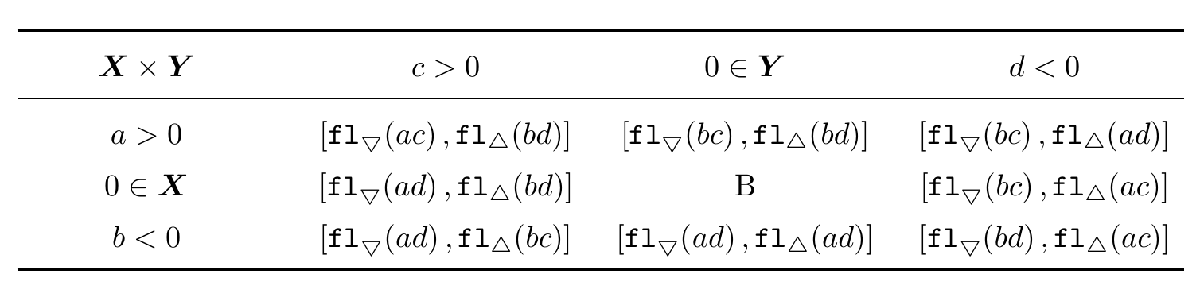

﻿ただし B $\(=[\min\{\mathtt{fl}_{\bigtriangledown}\!\left(ad\right),\mathtt{fl}_{\bigtriangledown}\!\left(bc\right)\},\max\{\mathtt{fl}_{\bigtriangleup}\!\left(ad\right),\mathtt{fl}_{\bigtriangleup}\!\left(bc\right)\}].\)$

### ﻿ベクトル・行列の区間演算

﻿上で述べた丸めの向きを制御することにより、ベクトル $\(x,y\in\mathbb{F}^n\)$ の内積 $\(x^Ty\)$、行列 $\(A, B\in\mathbb{F}^{n\times n}\)$ の積、あるいは、ベクトル行列積 $\(Ax\)$ の結果を区間で厳密に包含することができる。


$$\[
\mathtt{fl}_{\bigtriangledown}\!\left(x^Ty\right)\le x^Ty\le\mathtt{fl}_{\bigtriangleup}\!\left(x^Ty\right)
\]$$



$$\[
\mathtt{fl}_{\bigtriangledown}\!\left(Ax\right)\le Ax\le\mathtt{fl}_{\bigtriangleup}\!\left(Ax\right)
\]$$



$$\[
\mathtt{fl}_{\bigtriangledown}\!\left(AB\right)\le AB\le\mathtt{fl}_{\bigtriangleup}\!\left(AB\right)
\]$$


このようにすると丸め方向の制御で区間演算が容易にできる。しかし、行列ベクトル積、行列積を高速に実装することは職人芸のレベルの難しさである（例えば、キャシュサイズをみて最適なブロック分割などを行う）。そのため通常は数値計算ライブラリを利用するのが主流である。